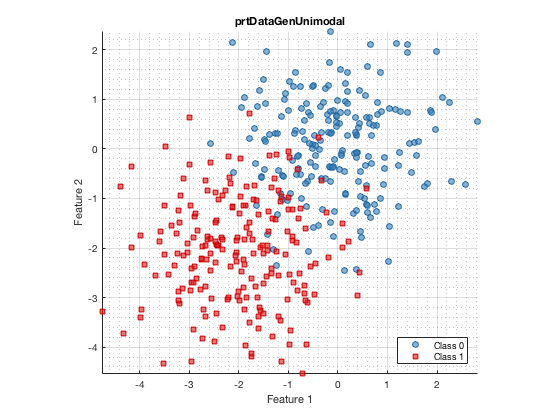

mu0 = [0,0];
mu1 = [-2,-2];
Sigma = eye(2); %diag([1,13]);
N = 200;
ds = prtDataGenUnimodal(N,mu0,mu1,Sigma,Sigma);
plot(ds)
axis equal tight

X = ds.X;
Y = ds.getTargetsAsBinaryMatrix;
Y = Y-mean(Y,1);

S = X'*Y

S =    1.0e+02 *

   1.974222998949794  -1.974222998949794
   2.118545367250750  -2.118545367250750


% S(i,j) is the covariance between feature i and class j

nComponents = 1;
R = zeros(size(X,2),nComponents);
Q = zeros(size(Y,2),nComponents);
for iVec = 1:nComponents
    [U,S,V] = svd(S)
    
    r = U(:,1); % We only need the first solution
    t = X*r; % the current score for X
    t = t - mean(t);
    t = t./norm(t);
    q = Y'*t; % the current loadings for Y
    
    % To deflate S project onto the normalized V 
    % We need to make sure that V is really orthogonal
    % This is simple Gram-Schimdt
    v = X'*t;
    if iVec > 1
        v = v - V(:,1:(iVec-1))*(V(:,1:(iVec-1)).'*v);
        u = u - T(:,1:(iVec-1))*(T(:,1:(iVec-1)).'*u);
    end
    v = v ./ norm(v);
    % Deflate S
    S = S - v*(v'*S);
    
    R(:,iVec) = r; % X,Y Covariance Orthogonal Decomposition
    Q(:,iVec) = q; % Y Loadings
end

U =   -0.681748501230849  -0.731586618979251
  -0.731586618979251   0.681748501230849


S =    1.0e+02 *

   4.095312179231747                   0
                   0   0.000000000000000


V =   -0.707106781186547   0.707106781186547
   0.707106781186547   0.707106781186547


Bpls = R*Q'

Bpls =    5.560782719014831  -5.560782719014831
   5.967294714894815  -5.967294714894815


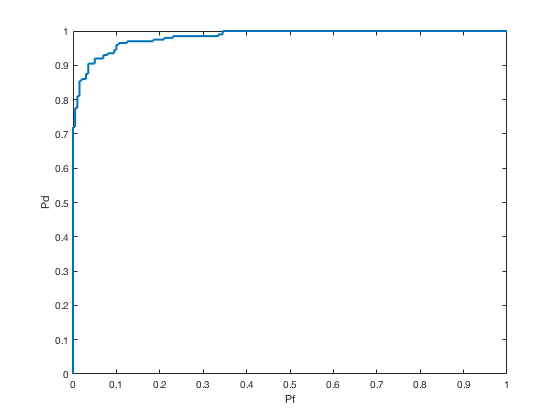

cls = prtClassLinearManual('w',Bpls(:,end));
prtScoreRoc(cls.run(ds))